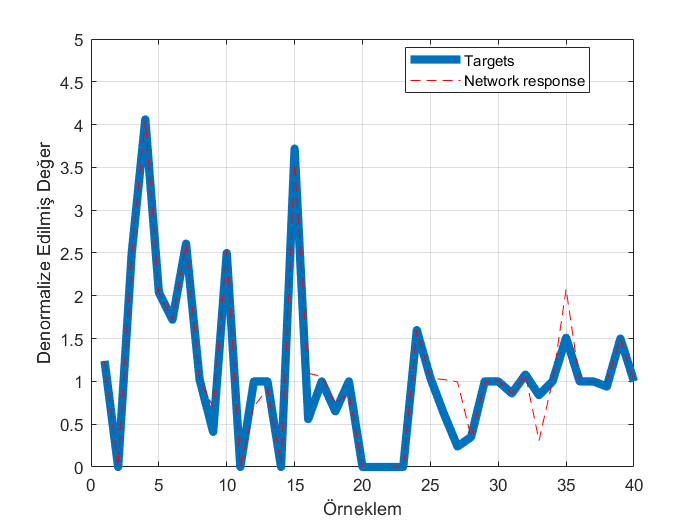

close all, clear  clc, format compact

data = xlsread('C:\Users\tcttn\Desktop\matlab\data2.xlsx');

%D = data(:,end);

data_normalized = normalize(data,'range');
data = data_normalized;
input_train = data(1:40,1:2);
target_train = data(1:40,end);
input_test = data(41:50,1:2);
target_test = data(41:50,end);

P = input_train';
T= target_train';

PT = input_test';
TT = target_test';

net = feedforwardnet(50,'trainlm');

net.layers{1}.transferFcn = 'logsig';
%net.layers{2}.transferFcn = 'tansig';
%net.layers{3}.transferFcn = 'tansig';
%net.layers{4}.transferFcn = 'tansig';

net.trainParam.epochs = 1000;
net.trainParam.goal = 1e-5;
net.trainParam.lr = 0.001;
net.trainParam.show = NaN;
net.trainParam.mc=0;

%net.divideParam.trainRatio = 0.8;
%net.divideParam.valRatio = 0; 
%net.divideParam.testRatio = 0.2; 

net = init(net);
[net,tr,Y,E] = train(net,P,T);
a=sim(net,P);

DT = T*4.06;
R = Y*4.06;

view(net);

figure(2)
plot(DT','linewidth',5)
hold on
plot(R','r--')
grid on
legend('Targets','Network response','location','best')
ylim([0 5]);
xlabel("Örneklem");
ylabel("Denormalize Edilmiş Değer");



YT = sim(net,PT);
YT= (YT*4.06)

YT =     0.2690    2.0786    0.2175    0.8834    1.3656    2.4567    0.7380    0.8759    0.9081    3.0824


TT= ((TT'*4.06))

TT =     1.1500
    2.0000
    1.5000
    2.1500
    2.8000
    2.5900
    1.5400
    2.0000
    2.6100
    3.0600


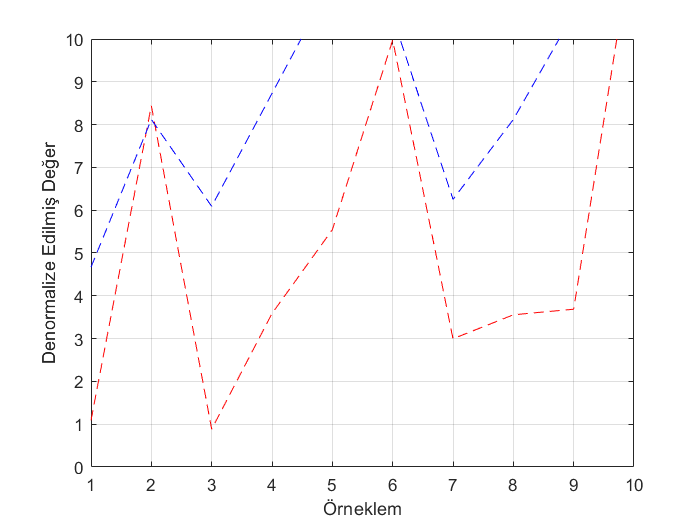

figure(3)
plot((YT'*4.06),'r--')
hold on
grid on
plot((TT'*4.06),'b--')
ylim([0 10]);
xlabel("Örneklem");
ylabel("Denormalize Edilmiş Değer");